## Загрузка данных

close all;
clear variables;
av = fscanf(fopen('air.txt', 'r'), '%f', [2 Inf]);
bv = fscanf(fopen('breath.txt', 'r'), '%f', [2 Inf]);
T = fscanf(fopen('totalTime.txt', 'r'), '%f');
temp = fscanf(fopen('temperature.txt', 'r'), '%f');
sf = fscanf(fopen('samplingFrequency.txt', 'r'), '%f');
wf = fscanf(fopen('volumeFractionWater.txt', 'r'), '%f');

fclose('all');
TV = (0:(1/sf):T)';
l = 1.158;
windowSize = 5;
b = (1/windowSize)*ones(1, windowSize);
a = 1;

aF1 = filter(b, a, av(1, :));
aF2 = filter(b, a, av(2, :));
bF1 = filter(b, a, bv(1, :));
bF2 = filter(b, a, bv(2, :));

start = 30;

aF1 = aF1(:, start:end);
aF2 = aF2(:, start:end);
bF1 = bF1(:, start:end);
bF2 = bF2(:, start:end);

T = TV(start:end)';

callibrA1 = polyfit(T, aF1, 3);
callibrA2 = polyfit(T, aF2, 3);
callibrB1 = polyfit(T, bF1, 3);
callibrB2 = polyfit(T, bF2, 3);

a1 = aF1 - polyval(callibrA1, T);
aN1 = a1./max(a1);
a2 = aF2 - polyval(callibrA2, T);
aN2 = a2./max(a2);
b1 = bF1 - polyval(callibrB1, T);
bN1 = b1./max(b1);
b2 = bF2 - polyval(callibrB2, T);
bN2 = b2./ max(b2);

## **Первый график**

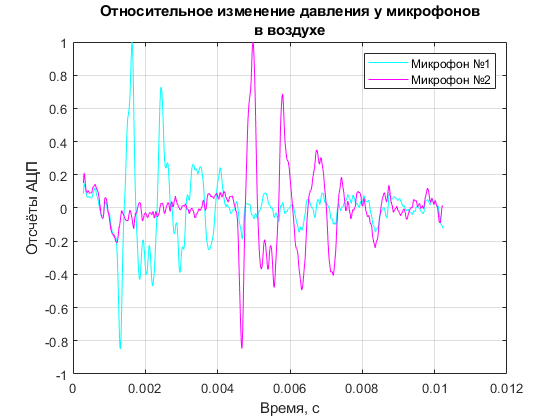

F1 = figure();

plot(T, aN1, 'c');
hold on;
plot(T, aN2, 'm');
hold off;
grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе'});
ylabel('Отсчёты АЦП');
xlabel('Время, с');
legend('Микрофон №1', 'Микрофон №2');
saveas(F1, "air.png")

## **Второй график**

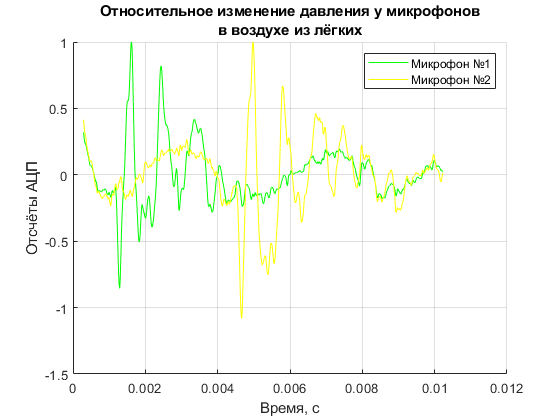

F2 = figure();

hold on;
plot(T, bN1, 'g');
plot(T, bN2,'y');
hold off;
grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе из лёгких'});
ylabel('Отсчёты АЦП');
xlabel('Время, с');
legend('Микрофон №1', 'Микрофон №2')
saveas(F2, "breath.png");


tA1 = T(aN1 == 1);
tA2 = T(aN2 == 1);

da = tA2 - tA1;
Va = l/da;

tB1 = T(bN1 == 1);
tB2 = T(bN2 == 1);

db = tB2 - tB1;
Vb = l/db;

R = 8.314;
Ma = 28.97;
MH2O = 18.01;
MCO2 = 44.01;
CpA = 1.0036;
CpH2O = 1.863;
CpCO2 = 0.838;
CvA = 0.7166;
CvH2O = 1.403;
CvCO2 = 0.649;
frCO2 = 0:0.00001:0.02;

p = Vb*ones(1, length(frCO2));
M = (1-wf-frCO2)*Ma + wf*MH2O + frCO2*MCO2;
Cp = CpA*(1-wf-frCO2)*Ma+CpH2O*wf*MH2O+CpCO2*frCO2*MCO2;
Cv = CvA*(1-wf-frCO2)*Ma+CvH2O*wf*MH2O+CvCO2*frCO2*MCO2;
g = Cp./Cv;
p1 = sqrt(1000*g*R*(temp+273.15)./M);
n = frCO2(p1 <= Vb);
n = n(1);

## **Третий график**

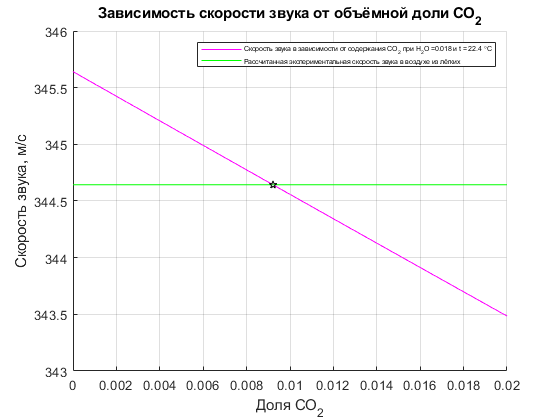

F3 = figure();

hold on;
plot(frCO2, p1,'m');
plot(frCO2, p,'g');
plot(n, Vb, 'kp');
hold off;
grid on;
title('Зависимость скорости звука от объёмной доли CO_2');
ylabel('Скорость звука, м/с');
xlabel('Доля CO_2');
legend(['Скорость звука в зависимости от содержания CO_2 при H_2O =', num2str(wf),' и t = ', num2str(temp), ' \circC'], 'Рассчитанная экспериментальная скорость звука в воздухе из лёгких','fontsize',5);
saveas(F3, "velocity.png");